# Example 6.22: Classification for Fault Detection in Reactor

Note: this script reproduces Example 6.22 (Section 6.4) of **Statistics for Chemical Engineers**: logistic regression to detect faults of the Gibbs reactor. Victor Z UW-Madison, 2020 logistic classification for gibbs data [https://www.mathworks.com/help/stats/fitclinear.html](https://www.mathworks.com/help/stats/fitclinear.html)

clc; clear all; close all hidden;

## Data

create data set

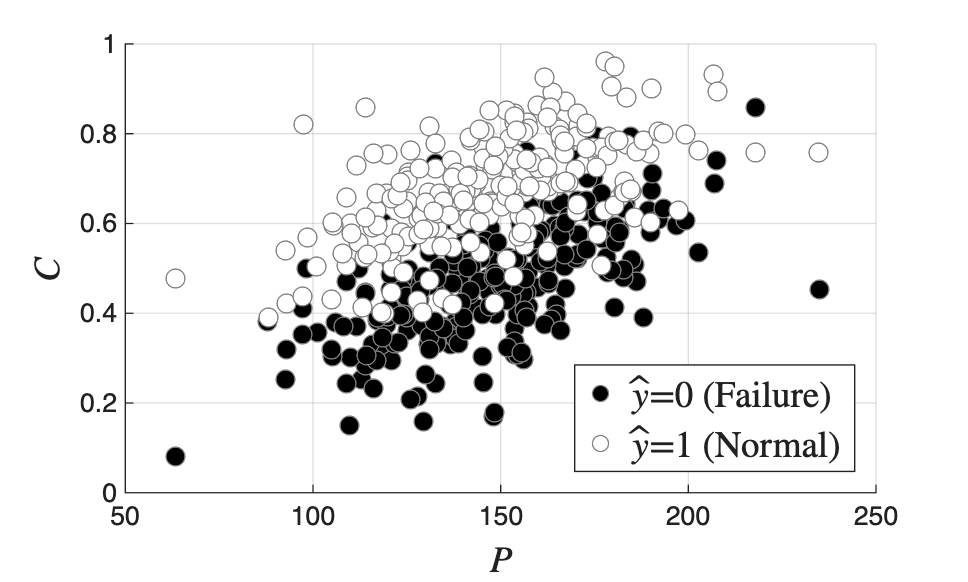

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
load ('./Data/gibbs_lowtemp_class.dat')
datalow=gibbs_lowtemp_class;
data=[datahigh;datalow];
datan=data;
n=length(datan);
% assign labels
for i=1:n
    if datan(i,1)==583.15
        datan(i,1)=1; % control normal
    else
        datan(i,1)=0; % control failure
    end
end

% corrupt data with noise to hide pattern (as we increase noise, confusion
% increases)
rng(1); % For reproducibility 
x1 = datan(:,2)+randn(n,1)*0.1;
x2 = datan(:,3)+randn(n,1)*0.1;
y=datan(:,1);
X=[x1 x2];

% visualize the data
figure(1); hold on;
h1 = scatter(x1(y==0),x2(y==0),50,'k','filled');  % black dots for 0
h2 = scatter(x1(y==1),x2(y==1),50,'w','filled');  % white dots for 1
set([h1 h2],'MarkerEdgeColor',[.5 .5 .5]);        % outline dots in gray
legend([h1 h2],{'$\hat{y}$=0 (Failure)' '$\hat{y}$=1 (Normal)'},'Location','SouthEast','Interpreter','latex','FontSize',14);
xlabel('$P$','Interpreter','latex','FontSize', 14)
ylabel('$C$','Interpreter','latex','FontSize', 14)
grid on
print -depsc ch6_gibbs_logistic_data.eps

## Logistic model

train model

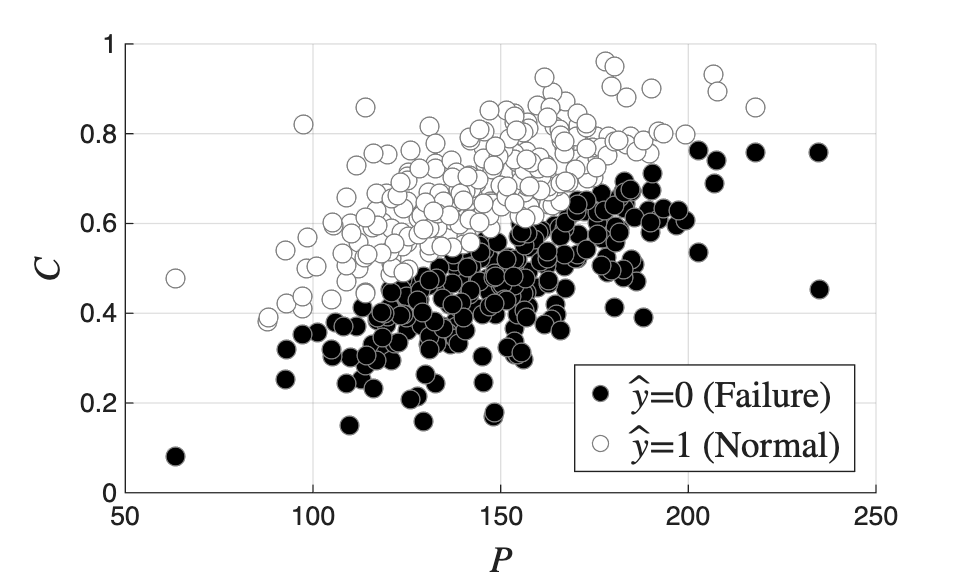

rng(1); % For reproducibility 
[Mdl,FitInfo] = fitclinear(X,y,'Learner','logistic');

% predict
[ypred,Score] = predict(Mdl,X);
% Score indicates probability that the i-th prediction is in either class

% visualize the predictions
figure(2); hold on;
h1 = scatter(x1(ypred==0),x2(ypred==0),50,'k','filled');  % black dots for 0
h2 = scatter(x1(ypred==1),x2(ypred==1),50,'w','filled');  % white dots for 1
set([h1 h2],'MarkerEdgeColor',[.5 .5 .5]);        % outline dots in gray
legend([h1 h2],{'$\hat{y}$=0 (Failure)' '$\hat{y}$=1 (Normal)'},'Location','SouthEast','Interpreter','latex','FontSize',14);
xlabel('$P$','Interpreter','latex','FontSize', 14)
ylabel('$C$','Interpreter','latex','FontSize', 14)
grid on
print -depsc ch6_gibbs_logistic_prediction.eps

## Confusion matrix

confusion matrix

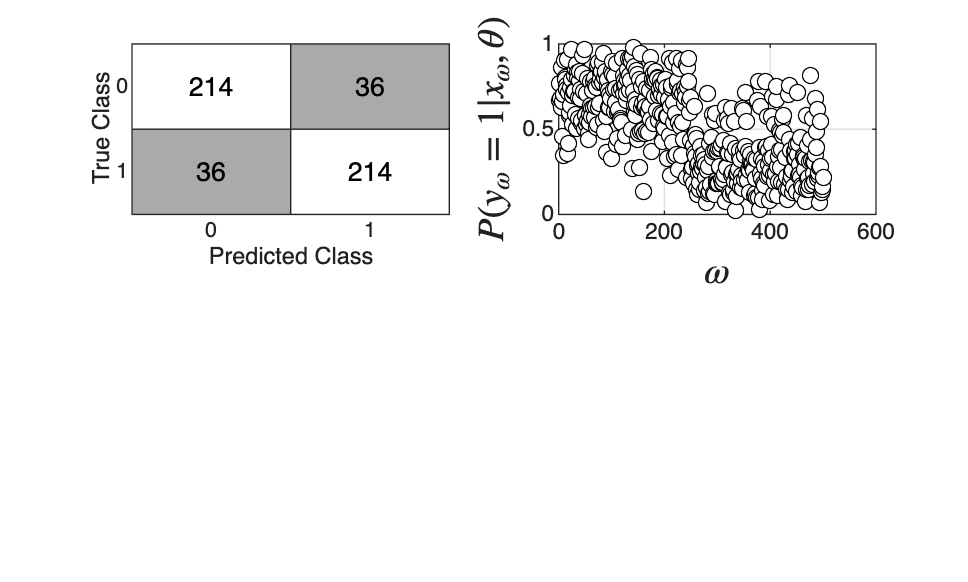

figure(3)
subplot(2,2,1)
ConfusionTrain = confusionchart(y,ypred,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);

% show probabilities
subplot(2,2,2)
plot(Score(:,1),'blacko','MarkerFaceColor','w')
xlabel('$\omega$','Interpreter','latex','FontSize', 14)
ylabel('$P(y_\omega=1|x_\omega,\theta)$','Interpreter','latex','FontSize', 14)
grid on
print -depsc ch6_gibbs_logistic_confusion.eps

## perform crossvalidation

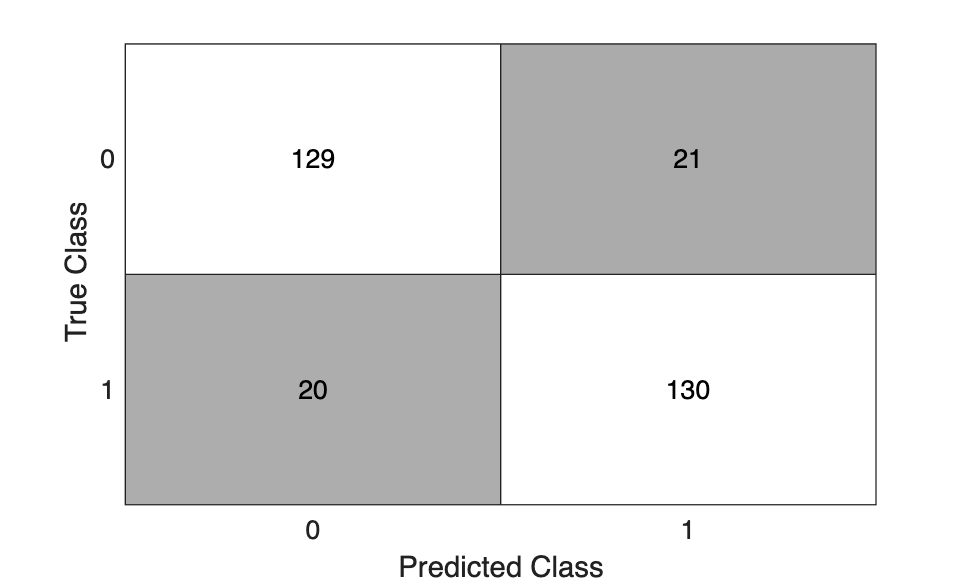

% splitting data set into train and test
Ystats=y;
CVMdl = fitclinear(X,Ystats,'Learner','logistic','Holdout',0.40);
Mdl = CVMdl.Trained{1};

trainIdx = training(CVMdl.Partition);
testIdx = test(CVMdl.Partition);
labelTrain = predict(Mdl,X(trainIdx,:));
labelTest = predict(Mdl,X(testIdx,:));

%Construct a confusion matrix for the training data.
figure(5)
ConfusionTrain = confusionchart(Ystats(trainIdx),labelTrain,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);

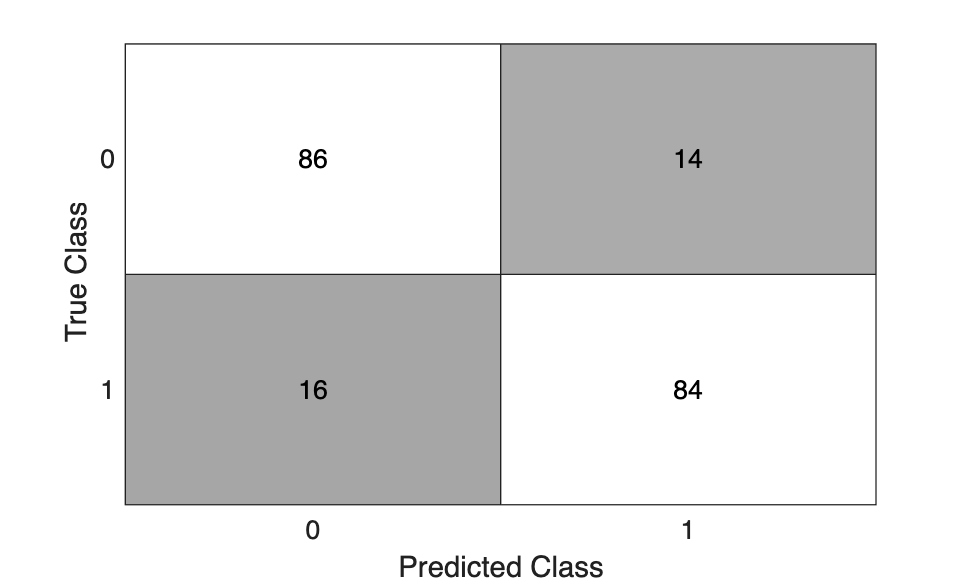


%Construct a confusion matrix for the test data.
figure(6)
ConfusionTest = confusionchart(Ystats(testIdx),labelTest,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);

## Note

As in the book, the model separates the classes well; cross-validation should be used to check that it generalizes to new data.